Pstar = @(x) exp(-x.^2) .* (2 + sin(x*5) + sin(x*2))

Pstar = function_handle with value:
    @(x)exp(-x.^2).*(2+sin(x*5)+sin(x*2))


N = 100

N =    100


proposalWidth = 1

proposalWidth =      1


L = 6

L =      6


Pstar = function_handle with value:
    @(f)f.^(a+nH-1).*(1-f).^(N-nH+b-1)*nchoosek(N,nH)


N =         1000


proposalWidth =    0.025000000000000


L =      1


X =    0.134897098869205
   0.134897098869205
   0.134897098869205
  -1.314200193969534
  -0.980689360903729
  -0.589335756470828
  -0.137656337542590
  -0.137656337542590
   0.046032758319352
   0.046032758319352
   0.046032758319352
   0.046032758319352
   0.501062314763686
   0.501062314763686
   0.166175375799639
   0.166175375799639
   0.166175375799639
  -0.951463307465569
   0.309195401655327
   0.309195401655327
   0.241329848112640
   0.046108650213885
   0.046108650213885
   0.046108650213885
   0.069154274638990
   0.120444630487765
   0.120444630487765
   0.120444630487765
   0.120444630487765
   0.120444630487765
   0.120444630487765
   0.303671893489202
  -0.726095650077419
   0.223126181053604
   0.223126181053604
   0.358301123153059
   0.358301123153059
   0.619707447208442
   0.619707447208442
   0.457369774404614
   0.311315140073088
   0.311315140073088
   0.311315140073088
   0.311315140073088
   0.311315140073088
   0.311315140073088
   0.311315140073088
   0.1190

X = MHsimple

X =   -0.049055328169913
  -0.049055328169913
   0.411564476503113
   0.411564476503113
   0.411564476503113
   0.305009324937473
   0.305009324937473
   0.305009324937473
   0.305009324937473
   0.178997964821039
   0.475169148830262
   0.475169148830262
   0.345241518339995
   0.465573088656839
   0.465573088656839
   0.465573088656839
   0.465573088656839
   0.519067896230607
   0.519067896230607
   0.286883034454980
   0.286883034454980
   0.286883034454980
   0.286883034454980
   0.286883034454980
   0.154411442277247
   0.154411442277247
   0.154411442277247
   0.154411442277247
   0.154411442277247
   0.718049026684271
   0.718049026684271
   0.718049026684271
   0.718049026684271
   0.718049026684271
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.319885919529191
   0.453912541348099
   0.453912541348099
   0.453912541348099
   0.453912541348099
   0.4539

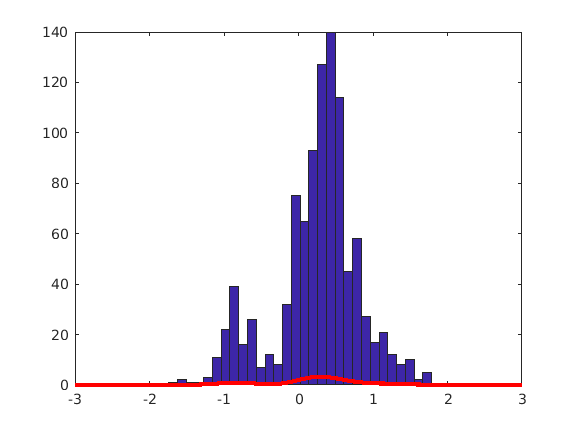

% PLotting the function with the posterior
xValues = -3:0.01:3;
figure(1); clf;
hist(X, 30, 'facealpha', 0.2, 'EdgeColor','w');

hold on;
plot(xValues, Pstar(xValues), 'Color', 'r', 'LineWidth', 3)

Pstar = @(f) f .^ (a + nH - 1) .* (1 - f).^(N - nH + b-1) * nchoosek(N, nH)

Pstar = function_handle with value:
    @(f)f.^(a+nH-1).*(1-f).^(N-nH+b-1)*nchoosek(N,nH)


%N = 1000
proposalWidth = 0.025

proposalWidth =    0.025000000000000


L = 1

L =      1


xInit = 0.5

xInit =    0.500000000000000


a = 12;
b = 12;
nH = 5;
N = 50;

rng('default');
X = MetropolisSampling(N, L, proposalWidth, xInit, Pstar);

Undefined function or variable 'a'.

Error in TestMetropolisPosterior>@(f)f.^(a+nH-1).*(1-f).^(N-nH+b-1)*nchoosek(N,nH)

Error in MetropolisSampling (line 48)
        acceptProb = min(1, Pstar(muProposal) / Pstar(X(t))); % acceptance probability

X

% PLotting the function with the posterior
xValues = -3:0.01:3;
figure(1); clf;
hist(X, 30, 'facealpha', 0.2, 'EdgeColor','w');

hold on;
plot(xValues, Pstar(xValues), 'Color', 'r', 'LineWidth', 3)